clear
clc

## Vorraussetzungen

% Payload masse
mgd = 10 * 10^3 ; % [kg]
% TODO: Tragstruktur
m1 = mgd; %[ kg]

% Startplatzbedingungen
beta = 28.5; % [°] - Geografische Breite

% Konstanten
g = 9.80665; %  [m/s^2] - Erdbeschleunigung
om_E = 7.292115*10^(-5) % [rad/s] Winkelgeschwindigkeit der Erde

om_E = 7.2921e-05


g = 9.80665; %  [m/s^2] - Erdbeschleunigung
r0 = 6378.14; % [km]
h = 200; % [km]
r = h +r0 ; % [km]
mu = 398600; % [km^3/s^2]
be = 28.5; % [deg]
i = 55; % [deg] Gewünschte Inklination
r_0 = 6378140 % Erdradius

r_0 = 6378140

## Berechnung des Anriebsbedarfs

V_Kreis = sqrt(mu/(r))  % [m/s]

V_Kreis = 7.7843

V_star = sqrt(V_Kreis^2 + 2 * mu * (1/r0 - 1/r)) % [m/s]

V_star = 8.0246


V_Kreis = V_Kreis * 10^3

V_Kreis = 7.7843e+03

V_star = V_star * 10^3

V_star = 8.0246e+03


al_inertial = asind(cosd(i)/cosd(be)) % Startazimut im inertialsystem

al_inertial = 40.7431


V_rot = om_E * r_0 * cosd(be)

V_rot = 408.7390


V_Kreis_rot = sqrt((V_Kreis * sind(al_inertial) - V_rot)^2 + (V_Kreis * cosd(al_inertial))^2)

V_Kreis_rot = 7.5239e+03


dV_rot = V_Kreis - V_Kreis_rot

dV_rot = 260.3953

dV_Gewinne = dV_rot

dV_Gewinne = 260.3953


%al_rot = atand((V_Kreis * sind(al_inertial) - V_rot)/(V_Kreis * cosd(al_inertial)))

dV_Schwere = 1250

dV_Schwere = 1250

dV_Widerstand = 150 

dV_Widerstand = 150

dV_Steuerung = 30 

dV_Steuerung = 30

dV_Manoever = 75

dV_Manoever = 75


dV_Verluste = dV_Schwere + dV_Widerstand + dV_Steuerung

dV_Verluste = 1430


dV = V_star + dV_Verluste + dV_Manoever - dV_Gewinne

dV = 9.2692e+03


Isp_1 = 301; % [s] Kero/lox
Isp_2 = 460; % [s] hydro/lox
Isp_3 = 460; % [s] hydro/lox

rho_1 = 1.03; % [Mg/m^3]
rho_2 = 0.28; % [Mg/m^3] 

C_1 = Isp_1 * g % [m/s]    GL 5-6 & 5-5

C_1 = 2.9518e+03

C_2 = Isp_2 * g

C_2 = 4.5111e+03

C_3 = Isp_3 * g;

% C_q = (C_1 + C_2)/2;
U_0 = dV;
mu = 0.9;

## Berechnung

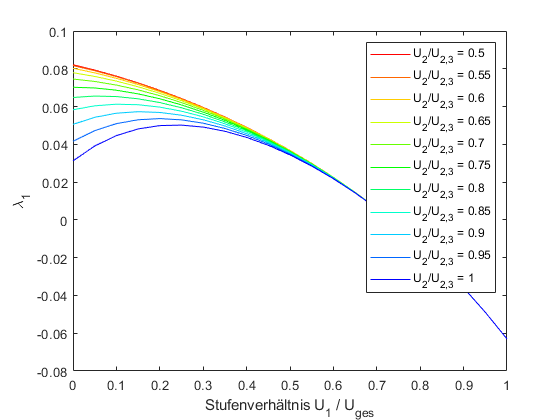

Stufungsfaktor = 0.4000

la1 = 0.0502

close all
plotColors = hsv(15);
i=0;

x = 0:0.05:1;
for y = 0.5:0.05:1
    i = i +1;
   
    U_1 = U_0 * x; % Gl 3-1
    U_2 = (U_0 - U_1) .* y;
    U_3 = U_0 - U_1 - U_2; % Gl 3-2

    la1 = 1./mu .* (1./exp(U_1./C_1) -1)+1;
    la2 = 1./mu .* (1./exp(U_2./C_2) -1)+1;
    la3 = 1./mu .* (1./exp(U_3./C_3) -1)+1;

    la = la1 .* la2 .* la3;
    
    % Ergebnisse darstellen
    desc = ['U_2/U_{2,3} = ',num2str(y)];
    plot(x,la,'Color', plotColors(i, :),'DisplayName',desc)
    hold all
    xlabel('Stufenverhältnis U_1 / U_{ges}')
    ylabel('\lambda_1')
    legend show
    
    % Optimaler Stufungsfaktor für den zweistufigen Fall ( y = 1 )
    if y == 1
        Stufungsfaktor = 0.4 % x(la==max(la))
        la1 = max(la)
    end
   
end


% Stufungsverhältnis

U_1 = U_0 * Stufungsfaktor % Gl 3-1

U_1 = 3.7077e+03

U_2 = (U_0 - U_1) 

U_2 = 5.5615e+03

n = 2;

C_q = C_1 * Stufungsfaktor + C_2 * (1 - Stufungsfaktor)

C_q = 3.8874e+03


Rges = exp(U_0/C_q); % 2-28
R_1 = exp(U_1/C_1);
R_2 = exp(U_2/C_2);

% Es gilt m67 = 0.02 * m8
% Es gilt m34 = m8/mu - m8
% Es gilt mu_T = (m67 + m8) / (m34 +m67 + m8)
% Es folgt mu_T = (0.02 * m8 + m8) / (m8/mu -m8 + 0.02 * m8 + m8)
% Es folgt mu_T = (0.02 + 1) / (1/mu -1 + 0.02 * 1 + 1) = 1.02/(1/mu +0.02)

mu_T = 1.02/(1/mu + 0.02)

mu_T = 0.9018


% Es gilt
% R_1 = Re_1 = m0_1/mc_1 % Gl. 2-10

zet_1 = -(1/R_1) + 1; % Gl. 2-45
zet_2 = -(1/R_2) + 1; 

eps_1 = zet_1 * (1/mu_T -1)+0.02 * zet_1; % Gl. 3-7
eps_2 = zet_2 * (1/mu_T -1)+0.02 * zet_2;
eps_0 = (eps_1 + eps_2)/2;

Mgd = (Rges^(-1/n) - eps_0)^(-n)

Mgd = 22.3007


m0 = Mgd * m1  % [kg] Gl 3-9

m0 = 2.2301e+05


mc_1 = m0 / exp(U_1/C_1); % Gl 2-28
m8_1 = m0 - mc_1;
m34_1 = m8_1/mu - m8_1;
mn_1 = m34_1 + m8_1

mn_1 = 1.7722e+05


mc_2 = (m0-mn_1) / exp(U_1/C_1);
m8_2 = m0-mn_1 - mc_2 ;
m34_2 = m8_2/mu - m8_2;
mn_2 = m34_2 + m8_2

mn_2 = 3.6384e+04

% Benötigter Schub für die Anfangsbeschleunigung der jeweiligen Raketenstufen
a_1 = 12.5; %[m/s^2]
a_2 = 10; %[m/s^2]

F_1 = m0 * a_1

F_1 = 2.7876e+06

F_2 = (m0-mn_1) * a_2

F_2 = 4.5783e+05

## Berechnen mit Massen

s_1 = massEst(m0,F_1,m8_1,rho_1);
s_2 = massEst(m0,F_2,m8_2,rho_2);

m0 = sum(s_1) + sum(s_2) + m1

m0 = 2.2612e+05

function [s] = massEst(m0,F,m8,rho)
m0 = m0 * 10^-3; % [Mg]
m8 = m8 * 10^-3; % [Mg]

m67 = 0.02*m8; % [Mg] Gl. 3-5
m41 = 8.09*10^-3 * F^0.9; % [kg] Gl. 3-11
m41 = m41 * 10^-3; % [Mg]
m3 = 0.1*(m8/(6*rho))^0.95 + 0.02 * m0; % [Mg] Gl. 3-12
m2 = (5.938 - 0.00404*(m3+m41)) * ((m3 + m41)/100); %  [Mg] Gl. 3-10

m2 = m2 * 10^3; % [kg]
m3 = m3 * 10^3; % [kg]
m4 = m41 * 10^3; % [kg]
m5 = 0;
m67 = m67 * 10^3; % [kg]
m8 = m8 * 10 ^3; % [kg]

s = [0, m2, m3, m4, m5, m67, 0, m8, 0];
end
